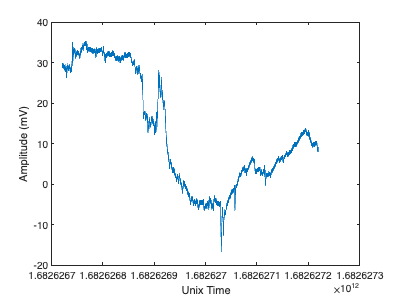

%% Housekeeping
clear
clc

%% Load in mat file
load Trial2_2.Thu15h28m52s_Session2_Shimmer_022D_Calibrated_SD.mat
UnixTime = Shimmer_022D_TimestampSync_Unix_CAL;
Amplitude = Shimmer_022D_ECG_CAL;

%% Plot raw ECG data vs Unix time
figure
plot(UnixTime,Amplitude)
hold on
xlabel('Unix Time')
ylabel('Amplitude (mV)')

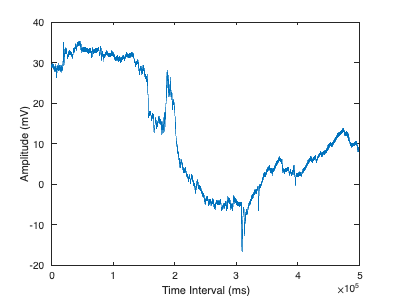


%% Create time interval from Unix
i = 0;
TimeInterval = zeros(length(UnixTime)+1,1);
for i = 1:length(UnixTime)-1
    TimeInterval(i+1) = TimeInterval(i)+(UnixTime(i+1)-UnixTime(i));
end

% Plot raw ECG data vs Time (ms)
TimeInterval(end) = [];
figure
plot(TimeInterval,Amplitude)
hold on
xlabel('Time Interval (ms)')
ylabel('Amplitude (mV)')

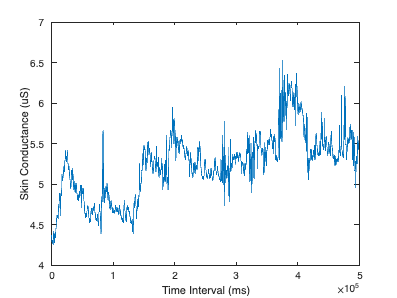


% Load in GSR data
SkinConductance = Shimmer_022D_GSR_CAL;

% Plot GSR vs Time (ms)
figure
plot(TimeInterval,SkinConductance)
hold on
xlabel('Time Interval (ms)')
ylabel('Skin Conductance (uS)')